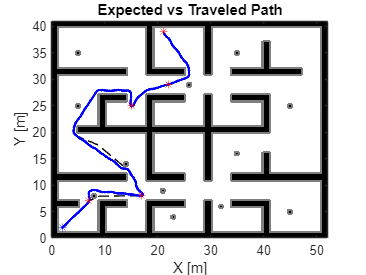

figure
show(visualMap)
hold on
plot(Waypoints(1, 1), Waypoints(1, 2),"*", 'color',"#0072BD",'MarkerSize',10, LineWidth=2);
plot(Waypoints(2:end, 1), Waypoints(2:end, 2),"r*", 'MarkerSize',10, LineWidth=2);
plot(interpolatedPath(:,1), interpolatedPath(:,2), 'k--')
plot(Pose(:,1),Pose(:,2), "b", 'LineWidth', 2)

title('Expected vs Traveled Path','FontSize', 20)
xlabel('X [m]')
ylabel('Y [m]')

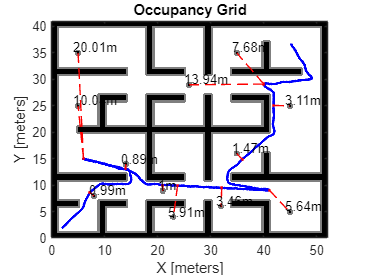

minDistances=zeros(size(obstacles,1),1);
minIdx=zeros(size(obstacles,1),1);
for i = 1:size(obstacles,1)
    [minDistances(i), minIdx(i)] = min(sqrt(sum((Pose(:,1:2)-obstacles(i,1:2)).^2,2))-0.15);
    
end


for i = 1:size(obstacles,1)
    plot(Pose(minIdx(i),1),Pose(minIdx(i),2), 'r.')
    plot([Pose(minIdx(i),1), obstacles(i,1)-0.05], [Pose(minIdx(i),2), obstacles(i,2)-0.05],'--', 'color',"#D95319")

    text(obstacles(i,1)-1, obstacles(i,2)+1, [num2str(round(minDistances(i),2)) 'm'])

end


title('Final Trial: 1','FontSize', 20)
xlabel('X [m]')
ylabel('Y [m]')
legend('','Waypoint','Planned Path','Traveled Path','','Obstacle Proximity')

wpDiststances=zeros(size(waypoints,1),1);
for i = 1:size(waypoints,1)
    wpDiststances(i) = min(sqrt(sum((Pose(:,1:2)-Waypoints(i+1,1:2)).^2,2)));
    
end

avgWpCapture = mean(wpDiststances)

avgWpCapture = 0.0724

nearestToObstacle = min(minDistances)
missionTime = time(end)

averageCrosstrack = sum(Offset)/length(Offset)

averageCrosstrack = 0.0414

RMSE = sqrt(mean(Offset.^2))

RMSE = 0.0475

nearestToObstacle = 0.9515